## Spike detection and spike rate analysis week 2, tutorial 1

In this live script we will read spike data into matlab with spike times aligned to auditory stimulus, recreate a raster plot aligned to stimulus and produce a Peristimulus time histogram (PSTH)

Tutorial using data from [https://github.com/yannikbauer/Raster_PSTH_SDF](https://github.com/yannikbauer/Raster_PSTH_SDF)

clc
close all
clear

# Part 1 - Read the spike data 

1. load the electrical recordings

load('sptimes.mat')


2. verify what kind of variable is contained in the opened .mat file

class(sptimes)


**Inspect the data**

A. What is the data size?

datasize = 

% datasize = ; 

B. What is the size of the first and second cell in sptimes?

Use indexing of the right cell with { }

% disp() 
% disp() 


C. Can you create a vector with two columns:

one column has values 1:size of the first cell; the second column has values 1:size of the second cell

*TIP: use [ ] to concatenate two single column vectors; TIP2: ***[a, b]*** and ***[a; b]*** result in different matrices*

% vector = ;


Why can't the two rows be side to side? How can the data be aggregated into a single vector?

D. What is the size of each cell in sptimes? What does that mean?

TIP: initialize an empty variable and add the sizes of each cell there

scells = [];

for c = 1:length(sptimes)
    scells(c) = length(sptimes{1,c}); % $$$
end

# Part 2 - Create a raster plot of the spikes 

3. open a figure and prepare a "subplot" with two panels stacked

figure('Units','normalized','Position',[0 0 .5 1])
ax = subplot(2,1,1); hold on

4. For each trial, plot dots at every x with a spike. Keep one line for each trial

TIP: use for loops across all trials

TIP2: for the position of each spike in time (x) you'll need a y value. Which value should that be?

5. Use pause() to create a figure that is slowly filled up

% ntrials = ; % $$$

for itrial = 1:ntrials

%     xspikes           =    ;   % Get all spikes of respective trial
%     yspikes      	    =    ;   % y values(trials)

    scatter(xspikes, yspikes, '.k')
%     
end
% set figure limits to last trial and to end of the recording window
ax.XLim             = [-.2 .3];
ax.YLim             = [0 ntrials];
ax.XTick            = [0 .2];
ax.XLabel.String  	= 'Time [s]';
ax.YLabel.String  	= 'Trials';


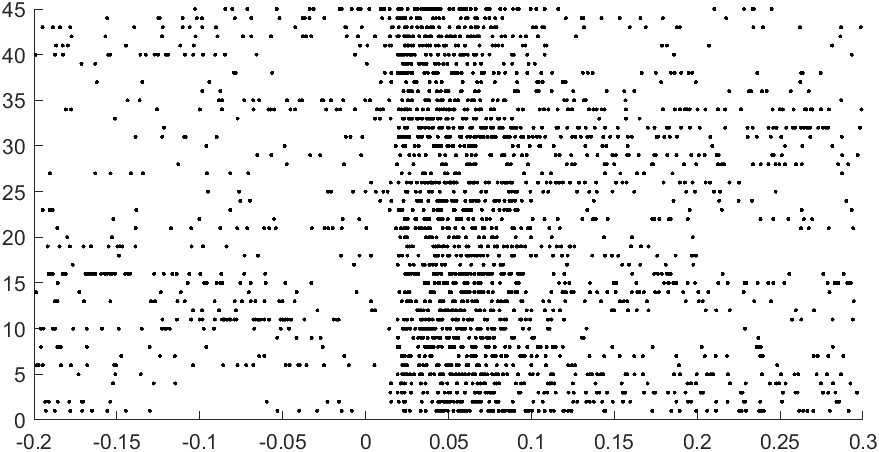

# Part 3 - Create a PSTH 

6 Add all spike times to a single vector

TIP: use a similar notation as before with [ ]. 

%% Peristimulus time histogram (PSTH)

% intialize vector for all spikes
allspike = [];
for iTrial = 1:length(sptimes)
     % Concatenate spikes of current trial to allspike
%     allspike             = ;   
end

7. Create a histogram with all spike timings and segmenting data into nbins

A. set nbins to the desired number of bins

******histogram* makes the histogram and automatically plots it

ax                  = subplot(2,1,2);
nbins               = 100;
h                   = histogram(allspike,nbins);
h.FaceColor         = 'k';

% ___________ set up axis, color and scaling of the figure ___________ %
mVal                = max(h.Values)+round(max(h.Values)*.1);
ax.XLim             = [-.2 .3];
ax.YLim             = [0 mVal];
ax.XTick            = [0 .2];
ax.XLabel.String  	= 'Time [s]';
ax.YLabel.String  	= 'Spikes/Bin';

# Final Question 

8. What is approximately the frequency of firing of this neuron outside of the stimulus and during stimulus?